## 1.0 Importing subject EEG

clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load

## 1.1 Load and import file as EEGLAB matrix

data_BLT = [];
data_P1 = [];

% Loop through the conditions and load the files
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % We will load the 10th file in the sorted list, just like your draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs), fs = EEG.srate; end
    
    if ismember(condition, {'BLA', 'BLT', 'P1'})
        % Isolate the epochs with Auditory onset using odd number indexes
        epoch_trials = 1:2:EEG.trials;
        
    elseif strcmp(condition, 'P2')
        % P2 has epochs preceding 500ms and 2000ms tactile events.
        % Indexes are provided in the Google Sheets file.
        warning('Indices for P2 must be loaded from the Google Sheets file. Using all trials as a placeholder.');
        epoch_trials = 1:EEG.trials; % REPLACE this with your loaded Google Sheet variable
        
    elseif strcmp(condition, 'P3')
        % P3 has epochs preceding 500ms and missing tactile events.
        % Indexes are provided in the Google Sheets file.
        warning('Indices for P3 must be loaded from the Google Sheets file. Using all trials as a placeholder.');
        epoch_trials = 1:EEG.trials; % REPLACE this with your loaded Google Sheet variable
        
    end
    
    % Extract and store the data based on which condition is currently looping
    if strcmp(condition, 'BLT')
        data_BLT = EEG.data(:, :, epoch_trials);
    elseif strcmp(condition, 'P1')
        data_P1 = EEG.data(:, :, epoch_trials);
    end
end

Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P2AvgBOS5.set for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P3AvgBOS5.set for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



nTime = size(data_BLT, 2);
time_ms_eeg = linspace(0, 3.5, nTime); % Rebuild the time vector

fprintf('Loaded BLT trials: %d | Loaded P1 trials: %d\n', size(data_BLT,3), size(data_P1,3));

Loaded BLT trials: 60 | Loaded P1 trials: 60


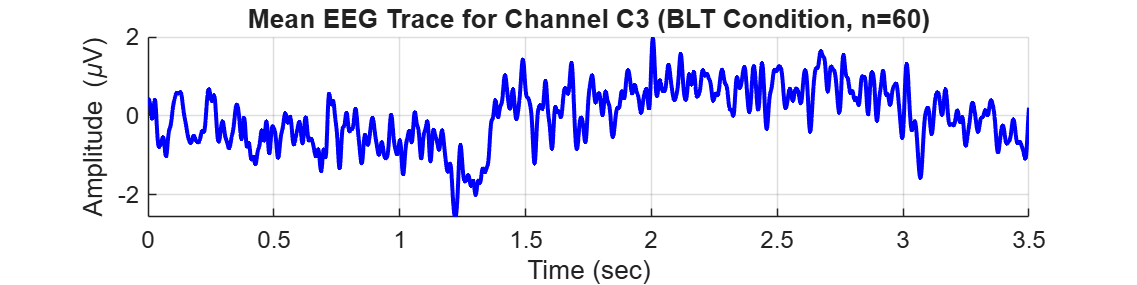

%% Plot Mean Trace for Channel C3 (BLT Condition)

% 1. Define the target channel index and name
target_ch_idx = 14; 
ch_name = 'C3';

% 2. Extract C3 data for the BLT condition
% data_BLT is (Channels x Time x Trials)
% squeeze() removes the singleton channel dimension, leaving a 2D matrix of (Time x Trials)
data_C3_BLT = squeeze(data_BLT(target_ch_idx, :, :));

% 3. Calculate the mean across the trial dimension (dimension 2 after squeezing)
mean_C3_BLT = mean(data_C3_BLT, 2);

% Optional: Calculate Standard Error of the Mean (SEM) if you want error bars later
% std_C3_BLT = std(data_C3_BLT, 0, 2);
% num_trials = size(data_C3_BLT, 2);
% sem_C3_BLT = std_C3_BLT / sqrt(num_trials);

% 4. Set up the figure and plot
figure('Position', [100, 100, 1200, 300]);
hold on;

% Plot the mean trace
plot(time_ms_eeg, mean_C3_BLT, 'b', 'LineWidth', 2);

% 5. Formatting
title(sprintf('Mean EEG Trace for Channel %s (BLT Condition, n=%d)', ch_name, size(data_C3_BLT, 2)), ...
    'FontSize', 16, 'FontWeight', 'bold');
xlabel('Time (sec)', 'FontSize', 14);
ylabel('Amplitude (\muV)', 'FontSize', 14);

% Fit the X-axis strictly to the bounds of your time vector
xlim([min(time_ms_eeg), max(time_ms_eeg)]);

grid on;
set(gca, 'FontSize', 12);
hold off;

## 1.2 Visualizing the EEG for the first trial

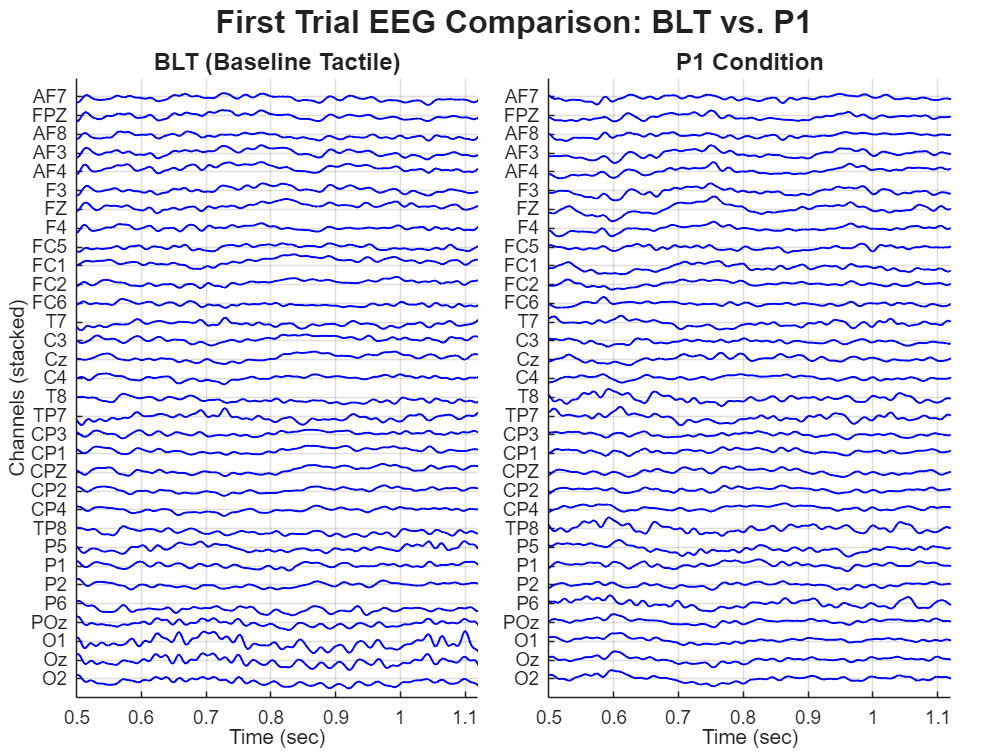

%% 1.2 Visualizing the EEG for the first trial (BLT vs P1)
num_channels_plot = 32;
T_subject = 3.5; % duration of each trial
display_channels = 1:1:num_channels_plot;
display_channels_str = {EEG.chanlocs.labels};

% Made the figure slightly wider (1600) to comfortably fit two plots side-by-side
figure('Position',[50 50 1600 1200])
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'First Trial EEG Comparison: BLT vs. P1', 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; % vertical spacing between channels
tick_positions = (num_channels_plot - display_channels) * offset;

% =========================
% PLOT 1: BLT Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_BLT(ch, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0.50 1.12]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));
set(gca,'FontSize',14);
title('BLT (Baseline Tactile)', 'FontSize', 18);
grid on;

% =========================
% PLOT 2: P1 Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_P1(ch, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0.50 1.12]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
% Y-axis labels repeated for easy reading across the wide figure
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));
set(gca,'FontSize',14);
title('P1 Condition', 'FontSize', 18);
grid on;

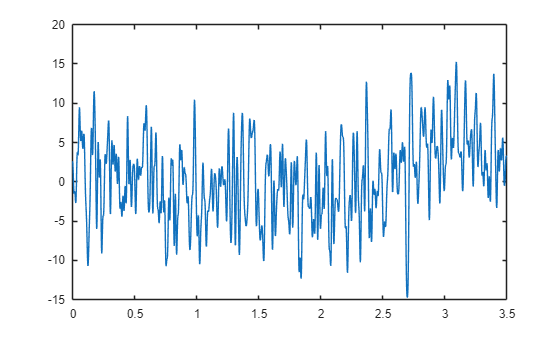

%plot(time_ms_eeg,nanmean(EEG.data(:,:,:),3)')

%plot(time_ms_eeg,nanmean(EEG.data(14,:,:),3)-nanmean(EEG.data(7,:,:),3))
figure();
plot(time_ms_eeg,EEG.data(25,:,12))

% Marchenko–Pastur threshold
data_one_trial = squeeze(data_BLT(:, :, 1));
eig_vals = eig(cov(data_one_trial'));
[N, T] = size(data_one_trial);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = param.N_F; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 5 PCs


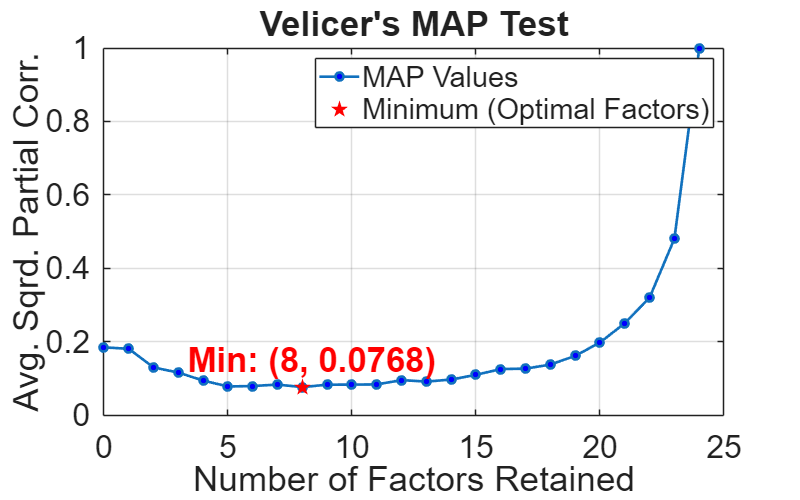

Velicer's MAP Test recommends retaining 8 factors.



[num_factors, map_values] = velicer_map(data_one_trial');


function [num_factors, map_values] = velicer_map(data)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.
%
% Inputs:
%   data - An (n x p) matrix of raw data (n observations, p variables).
%
% Outputs:
%   num_factors - The optimal number of factors to retain.
%   map_values  - A vector containing the MAP values at each step (from 0 to p-1 factors).

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    eigval = diag(eigval_mat);
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = eigvec(:, idx);
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        % Calculate the loadings for m components
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        
        % Reproduce the correlation matrix from m components
        part_cov = R - (A * A');
        
        % Compute the partial correlation matrix
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        
        % Isolate off-diagonal elements
        R_partial_off = R_partial - eye(p);
        
        % Calculate the average squared partial correlation
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    % Note: MATLAB is 1-indexed, so index 1 represents 0 factors.
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Optional: Plot the results to visualize the minimum
    figure('Position',[50 50 800 500]);
    plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    hold on;
    plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Highlight minimum
    coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
    text(num_factors, 0.2, coordinate_text, ...
        'VerticalAlignment', 'top', ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 26, ...
        'FontWeight', 'bold', ...
        'Color', 'r');
    xlabel('Number of Factors Retained');
    ylabel('Avg. Sqrd. Partial Corr.');
    title('Velicer''s MAP Test');
    legend('MAP Values', 'Minimum (Optimal Factors)');
    set(gca,'FontSize',24);
    grid on;
    hold off;
    
    % Output the result to the console
    fprintf('Velicer''s MAP Test recommends retaining %d factors.\n', num_factors);
end

## 2.0 Parameter setup for CVAE

% 0. Define the time window of interest and crop the data!
% Find indices where time is between 0.380 and 0.860 seconds
%% 2.0 Parameter setup for CVAE (2-Class: BLT vs P1)
% 0. Define the time window and crop BOTH datasets!
valid_time_idx = time_ms_eeg >= 0.500 & time_ms_eeg < 1.120; % 120 sec stim + 500 ms
time_cropped = time_ms_eeg(valid_time_idx);
nTime_cropped = length(time_cropped);

data_BLT_cropped = data_BLT(:, valid_time_idx, :);
data_P1_cropped  = data_P1(:, valid_time_idx, :);

% Ensure both datasets have the exact same number of trials before concatenating
min_trials = min(size(data_BLT_cropped, 3), size(data_P1_cropped, 3));
data_BLT_cropped = data_BLT_cropped(:, :, 1:min_trials);
data_P1_cropped  = data_P1_cropped(:, :, 1:min_trials);

% --- THE CONCATENATION ---
% Concatenate BLT and P1 along the TIME dimension (Dimension 2)
data_concat = cat(2, data_BLT_cropped, data_P1_cropped);
nTime_concat = size(data_concat, 2); % This is exactly double nTime_cropped

fprintf('Concatenated data shape: %d channels x %d time points x %d trials\n', ...
        size(data_concat, 1), size(data_concat, 2), size(data_concat, 3));

Concatenated data shape: 32 channels x 636 time points x 60 trials


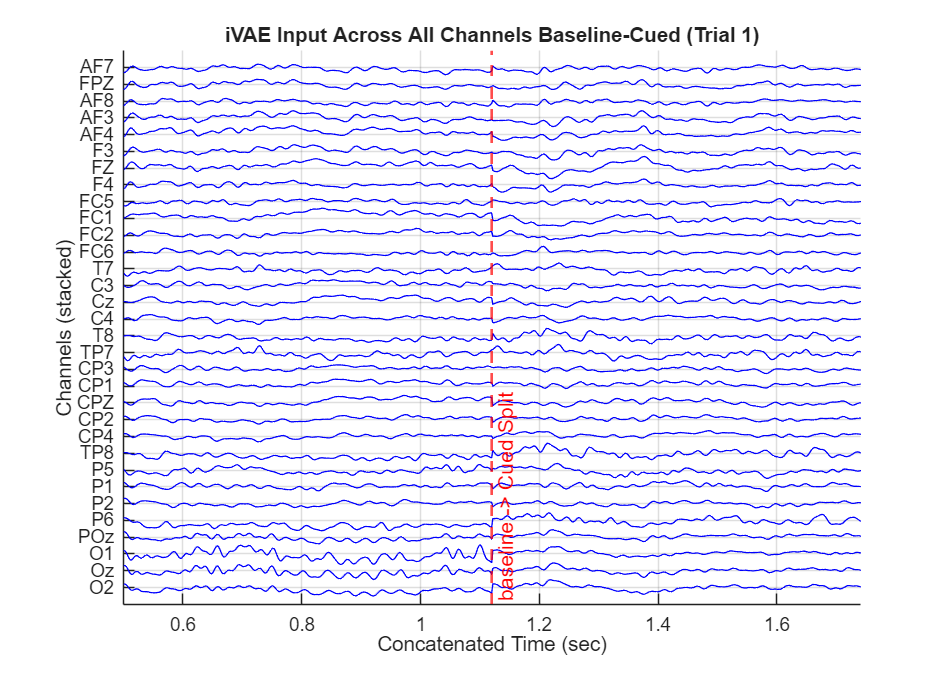

%% 1.2 Visualizing the iVAE Input (All Channels)

% Extract the 2D matrix by squeezing out the singleton 3rd dimension
% X_plot shape: (Channels x Time)
X_plot = squeeze(data_concat(:,:,1)); 

% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(X_plot, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

% Create a continuous time vector for the concatenated data
nTime_single = length(time_cropped);
dt = time_cropped(2) - time_cropped(1);

% Ensure time_cropped starts at 0.500 and ends at 1.120 as earlier
% Build concatenated time that runs from 0.500 to 1.740 (i.e., 0.500->1.120 then 1.120->1.740)
% We create the second segment by shifting time_cropped so its start is immediately after the first end.
first_segment = time_cropped;
second_segment = time_cropped + (time_cropped(end) - time_cropped(1)) + dt; 
% Concatenate
time_concat = [first_segment, second_segment];

% Recompute nTime_single in case it's used elsewhere as the split point
nTime_single = length(first_segment);

% Set up a single wide figure (no tiled layout needed since it's one concatenated block)
figure('Position',[50 50 1400 1000])
title(sprintf('iVAE Input Across All Channels Baseline-Cued (Trial %d)', 1), ...
      'FontSize', 24, 'FontWeight', 'bold');

% Adjusted offset for globally scaled data (standard deviation ~ 1)
offset = 30; 
tick_positions = (num_channels_plot - display_channels) * offset;

hold on
for ch = 1:num_channels_plot
    % Stack channels vertically and strictly use blue ('b')
    plot(time_concat, X_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
end

% Add a vertical boundary line to show where BLT ends and P1 begins
split_time = time_concat(nTime_single);
xline(split_time, 'r--', 'baseline -> Cued Split', 'LineWidth', 2, 'FontSize', 16, 'LabelVerticalAlignment', 'bottom');

hold off

% Fit the X-axis strictly to our concatenated time window
xlim([min(time_concat), max(time_concat)]); 
ylim([-offset, num_channels_plot*offset]);

xlabel('Concatenated Time (sec)'); 
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));

set(gca,'FontSize',14);
grid on;

% 1. Create the Condition Vector (C) for the concatenated super-trial
% Starting simple: 2 classes! (Class 1 = BLT, Class 2 = P1)
numClasses = 2; 
C_trial = zeros(numClasses, nTime_concat);

% --- Assign the 2 Classes ---
% The first half belongs to BLT
C_trial(1, 1:nTime_cropped) = 1; 

% The second half belongs to P1
C_trial(2, nTime_cropped+1:end) = 1;

% 2. Split data by whole trials (80% Train, 20% Test)
num_train_trials = floor(0.8 * min_trials);

rng(42); % For reproducibility
idx_rand = randperm(min_trials);
train_idx = idx_rand(1:num_train_trials);
test_idx = idx_rand(num_train_trials+1:end);

% Use the new concatenated array here
data_train = data_concat(:, :, train_idx);
data_test = data_concat(:, :, test_idx);

% 3. Reshape into 2D matrices for the network
X_train = reshape(data_train, num_ch, []);
X_test = reshape(data_test, num_ch, []);

% Rank of data
r = rank(X_train);

% 4. Replicate the Condition vector
C_train = repmat(C_trial, 1, length(train_idx));
C_test = repmat(C_trial, 1, length(test_idx));

% 5. Define CVAE Configuration
% NOTE: We are keeping the iVAE method and KL annealing!
cfg.method = "ivae"; 
cfg.bottleneckSize = num_factors; % num_sig_components, r-2
cfg.encoderLayerSizes = [64, 32];
cfg.decoderLayerSizes = [32, 64];
cfg.priorLayerSizes = [16];
cfg.epochs = 200;      
cfg.patience = 15; 
cfg.batchSize = 512;
cfg.learnRate = 5e-3;
cfg.beta = 0.1; 
cfg.warmupEpochs = 20;

## 2.1 Run CVAE for subject data

fprintf('Training CVAE model with early stopping...\n');

Training CVAE model with early stopping...


% Notice we are passing X_test and C_test now
[encNet, decNet, priorNet, info] = trainEEGCVAE(X_train, C_train, X_test, C_test, cfg);

Epoch 1/200 - Train Loss: 1415.4537 | Val Loss: 401.5229
Epoch 2/200 - Train Loss: 305.5144 | Val Loss: 312.6872
Epoch 3/200 - Train Loss: 277.6493 | Val Loss: 297.2307
Epoch 4/200 - Train Loss: 250.7411 | Val Loss: 255.8657
Epoch 5/200 - Train Loss: 217.4756 | Val Loss: 231.1926
Epoch 6/200 - Train Loss: 201.8218 | Val Loss: 221.6291
Epoch 7/200 - Train Loss: 190.7426 | Val Loss: 210.7175
Epoch 8/200 - Train Loss: 179.5797 | Val Loss: 202.2028
Epoch 9/200 - Train Loss: 172.8613 | Val Loss: 197.1334
Epoch 10/200 - Train Loss: 168.7955 | Val Loss: 193.0563
Epoch 11/200 - Train Loss: 165.7715 | Val Loss: 189.2825
Epoch 12/200 - Train Loss: 163.0013 | Val Loss: 184.7876
Epoch 13/200 - Train Loss: 159.7260 | Val Loss: 178.0816
Epoch 14/200 - Train Loss: 155.6516 | Val Loss: 169.8395
Epoch 15/200 - Train Loss: 150.5762 | Val Loss: 162.3844
Epoch 16/200 - Train Loss: 146.1838 | Val Loss: 155.0469
Epoch 17/200 - Train Loss: 142.3899 | Val Loss: 150.0160
Epoch 18/200 - Train Loss: 139.6373 | V

## 2.2 Plot Training and Validation Loss

fprintf('Plotting training and validation loss...\n');

Plotting training and validation loss...


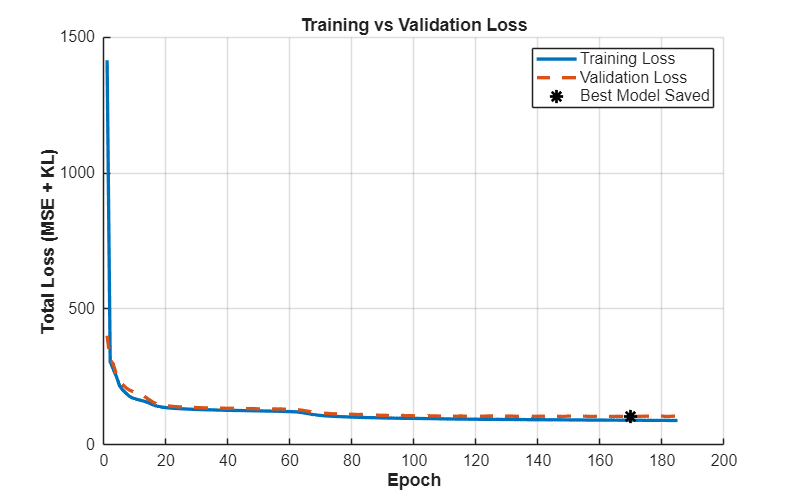

figure('Position', [150 150 800 500]);
hold on;
% Plot Train and Val loss
epochs_trained = length(info.lossHistory);
plot(1:epochs_trained, info.lossHistory, '-', 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Training Loss');
plot(1:epochs_trained, info.valLossHistory, '--', 'LineWidth', 2.5, 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'Validation Loss');

% Mark the best epoch (where the weights were actually saved)
[bestLoss, bestEpoch] = min(info.valLossHistory);
plot(bestEpoch, bestLoss, 'k*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Best Model Saved');
hold off;

grid on;
legend('Location', 'northeast', 'FontSize', 12);
xlabel('Epoch', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Total Loss (MSE + KL)', 'FontSize', 14, 'FontWeight', 'bold');
title('Training vs Validation Loss', 'FontSize', 16);
set(gca, 'FontSize', 12);

## 3.0 Extract Latent Representations (Inference on Test Data)

fprintf('Extracting latent representations for the Test Set...\n');

Extracting latent representations for the Test Set...



% Convert test data to dlarray format
X_test_dl = dlarray(X_test, 'CB');
C_test_dl = dlarray(C_test, 'CB');

% Concatenate Features (X) and Conditions (C) for the Encoder
XC_test = cat(1, X_test_dl, C_test_dl);

% Forward pass through the trained encoder to get the latent mean (zMu)
[zMu_test, zLogVar_test] = forward(encNet, XC_test);

% Extract the data from the deep learning array back into standard MATLAB matrices
latent_representations = extractdata(zMu_test);

fprintf('Latent representation extracted! Size: %d x %d\n', size(latent_representations, 1), size(latent_representations, 2));

Latent representation extracted! Size: 8 x 7632


%% 4.0 Visualizing Latent Space (Latent 1 vs. Others)
fprintf('Visualizing latent representations...\n');

Visualizing latent representations...


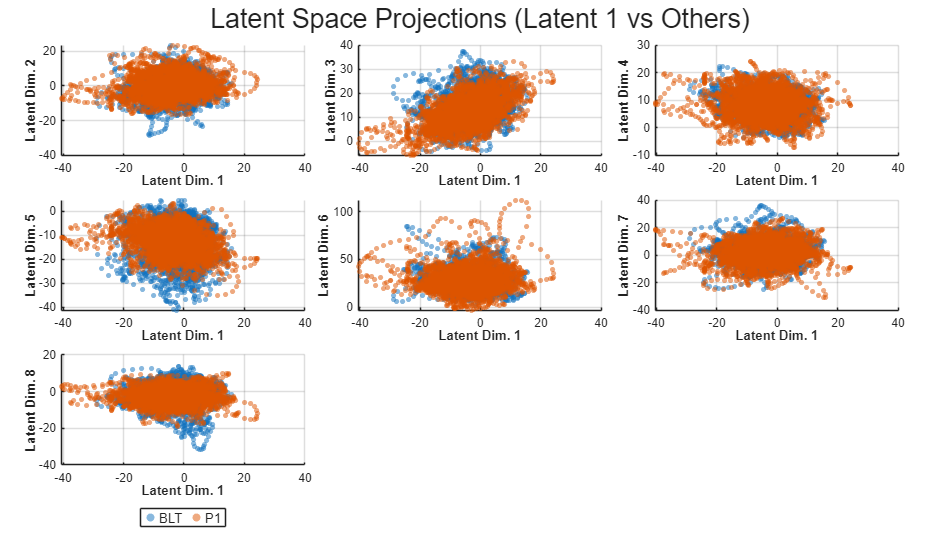


% 1. Convert one-hot encoded C_test back to categorical indices (1 to 4)
[~, condition_idx] = max(C_test, [], 1);
% condition_names = {'Before', 'Tactile', 'AFter 1', 'After 2'};
condition_names = {'BLT', 'P1'};
% 2. Setup colors and figure layout
colors = lines(length(condition_names)); % Generate distinct colors
num_latents = size(latent_representations, 1);

figure('Position', [100 100 1400 800]);
% tiledlayout is perfect for dynamically creating a grid of subplots
t = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact'); 
title(t, 'Latent Space Projections (Latent 1 vs Others)', 'FontSize', 20);

% 3. Loop through latent dimensions 2 through N
for i = 2:num_latents
    nexttile;
    hold on;
    
    % Plot each condition separately so we can build a clean legend
    for c = 1:length(condition_names)
        % Find all points belonging to the current condition
        idx = (condition_idx == c); 
        
        % Scatter plot: Latent 1 on X-axis, Latent 'i' on Y-axis
        scatter(latent_representations(1, idx), latent_representations(i, idx), ...
                15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5);
    end
    
    xlabel('Latent Dim. 1', 'FontWeight', 'bold');
    ylabel(sprintf('Latent Dim. %d', i), 'FontWeight', 'bold');
    grid on;
    
    hold off;
end
legend(condition_names, 'Orientation', 'horizontal', 'Location', 'southoutside', 'FontSize', 10);

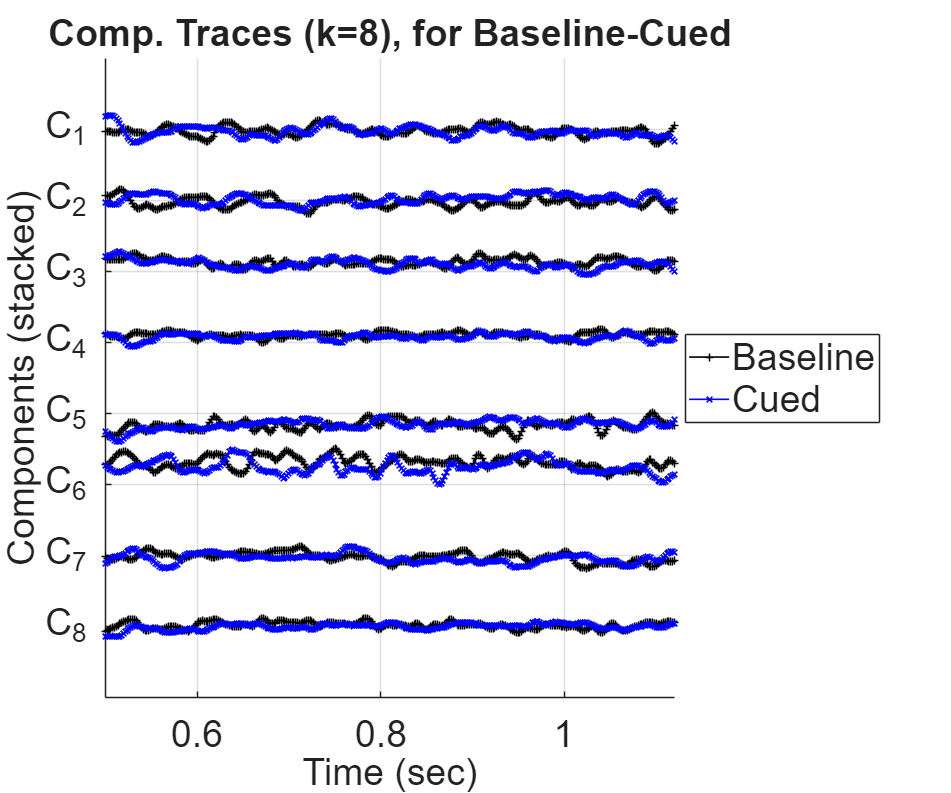

% 2. Component Tracesfor the first 1 seconds (matching your previous xlim)

time_vec = [time_cropped, time_cropped];
num_comps_plot = num_latents;

% Define time vector ;

% Setup Figure
fig2 = figure('Position', [50 50 1200 1000]);
hold on;

% --- Styling ---
% Calculate offset based on data range to prevent excessive overlap
% If the components are z-scored, an offset of 5-10 usually works well.
% Here we use a fixed offset similar to your EEG example.
offset = max(std(latent_representations( 1:num_comps_plot, :), 0, 1)) * 2; 
if offset == 0 || isnan(offset), offset = 10; end % Fallback

for pc = 1:num_comps_plot
    % Extract data for this component
    trace = latent_representations(pc,:);
    
    % Plot each component stacked (Component 1 at the top)
    % Using (num_comps_plot - pc) ensures C_1 is at the top of the y-axis
    y_shift = (num_comps_plot - pc) * offset;
    plot(time_cropped, trace(1:nTime_cropped) + y_shift, 'Color', 'k', 'Marker','+','LineWidth', 1.2, 'HandleVisibility', 'off');
    plot(time_cropped, trace(nTime_cropped+1:nTime_concat) + y_shift, 'Color', 'b','Marker','x', 'LineWidth', 1.2, 'HandleVisibility', 'off');
end

% Plotting NaN ensures nothing is drawn, but the legend can still read the color/style
h_BLT = plot(NaN, NaN, 'Color', 'k', 'Marker','+','LineWidth', 1.2, 'DisplayName', 'Baseline');
h_P1  = plot(NaN, NaN, 'Color', 'b','Marker','x', 'LineWidth', 1.2, 'DisplayName', 'Cued');

hold off;

% --- Formatting ---
% xlim([0 t_plot_sec]);
ylim([-offset, num_comps_plot * offset]);
xlim([0.5 1.12]);
xlabel('Time (sec)');
ylabel('Components (stacked)');
title(['Comp. Traces (k=' num2str(num_comps_plot) ')' ', for Baseline-Cued']);

% Set ticks to show component numbers clearly
yticks((0:num_comps_plot-1) * offset);
yticklabels(arrayfun(@(c) sprintf('C_{%d}', num_comps_plot - c), ...
    0:num_comps_plot-1, 'UniformOutput', false));
legend([h_BLT, h_P1], 'Location', 'eastoutside');
grid on;
set(findall(fig2, '-property', 'FontSize'), 'FontSize', 28);

## 4.1 Visualizing Latent Space using t-SNE


fprintf('Running t-SNE on 23-dimensional latent space. This might take a moment...\n');

Running t-SNE on 23-dimensional latent space. This might take a moment...


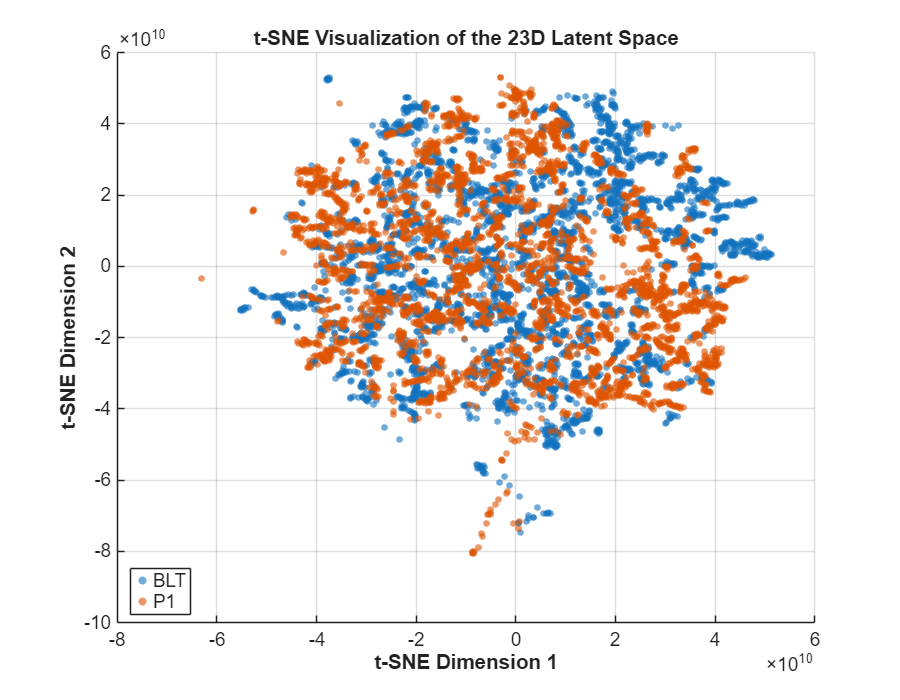


% 1. tsne expects data in format (Observations x Variables), so we transpose the matrix
latent_data_tsne = latent_representations'; 

% 2. Run t-SNE (compressing 23 dimensions down to 2)
% We set a random seed so the plot looks the same if you run it twice
rng(42); 
Y_tsne = tsne(latent_data_tsne, 'NumDimensions', 2, 'Standardize', true);

% 3. Get condition labels from the one-hot encoded C_test
[~, condition_idx] = max(C_test, [], 1);
% condition_names = {'Before', 'Tactile', 'After 1', 'After 2'};
condition_names = {'BLT', 'P1'};
% 4. Plot the t-SNE map
figure('Position', [200 200 900 700]);
colors = lines(length(condition_names));
hold on;

for c = 1:length(condition_names)
    % Find all points belonging to the current condition
    idx = (condition_idx == c); 
    
    % Scatter plot the t-SNE coordinates
    scatter(Y_tsne(idx, 1), Y_tsne(idx, 2), 25, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.6);
end
hold off;

grid on;
xlabel('t-SNE Dimension 1', 'FontWeight', 'bold');
ylabel('t-SNE Dimension 2', 'FontWeight', 'bold');
title('t-SNE Visualization of the 23D Latent Space', 'FontSize', 18);
legend(condition_names, 'Location', 'best', 'FontSize', 14);
set(gca, 'FontSize', 14);

#### 4.5 iVAE across trials

data_all_conds = struct();
time_ms_eeg = []; % Will populate on first load

for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Loading the 10th file in the sorted list as per original draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs)
        fs = EEG.srate;
    end
    
    % Rebuild time vector (assuming 3.5s epochs as in original draft)
    time_ms_eeg = linspace(0, 3.5, size(EEG.data, 2)); 
  
    % Extract odd/even trials based on condition
    if ismember(condition, {'BLT', 'P1', 'P2', 'P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end
    
    % KEEP ALL CHANNELS: Store cropped data as (Channels x Time x Trials)
    data_all_conds.(condition) = EEG.data(:, :, epoch_trials);
end

Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P2AvgBOS5.set for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P3AvgBOS5.set for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


valid_time_idx_BLT = time_ms_eeg >= 0.5000 & time_ms_eeg <= 1.1200; 
valid_time_idx_P13 = time_ms_eeg >= 1.0000 & time_ms_eeg < 1.621; 
valid_time_idx_P12 = time_ms_eeg >= 1.0000 & time_ms_eeg < 3.121; 

time_cropped_BLT = time_ms_eeg(valid_time_idx_BLT);
time_cropped_P12 = time_ms_eeg(valid_time_idx_P12);
time_cropped_P13 = time_ms_eeg(valid_time_idx_P13);

% 1. Determine the maximum number of balanced trials
min_trials = size(data_all_conds.P1, 3);

% 2. Generate independent random trial permutations
% (Using rng(42) ensures you can reproduce this exact "random" plot for your adviser later)
rng(42); 
rand_idx_BLT = randperm(min_trials);

% 3. Concatenate using the randomized trial indices
% Now, Trial 1 of BLT is concatenated with a completely random Trial M of P1
data_concat_all = cat(2, ...
                        ... % data_all_conds.BLT(:, valid_time_idx_BLT, rand_idx_BLT), ...
                        data_all_conds.P1(:, valid_time_idx_P13, rand_idx_BLT), ...
                        ... % data_all_conds.P2(:, valid_time_idx_P12, rand_idx_BLT)); %
                        data_all_conds.P3(:, valid_time_idx_P13, rand_idx_BLT));

total_samples = size(data_concat_all, 2);

fprintf('Concatenated data shape: %d channels x %d time points x %d trials\n', ...
        size(data_concat_all, 1), size(data_concat_all, 2), size(data_concat_all, 3));

Concatenated data shape: 32 channels x 636 time points x 60 trials


% 3. Globally scale the data to stabilize variance 
% (Dividing by global std preserves relative amplitude between channels)
% Compute global standard deviation across all elements (scalar).
% std(X_single_trial(:)) computes std over the entire matrix (not along rows or columns).
global_std_all = std(data_concat_all(:));
data_concat_all = data_concat_all / global_std_all;

% reshape ch x (time x trial) 
% 4. Append the singleton 3rd dimension so dPCA knows Time is dimension 2
X_iVAE_input = reshape(data_concat_all, size(data_concat_all, 1), size(data_concat_all, 2)* size(data_concat_all, 3), 1);
X_iVAE_input = double(squeeze(X_iVAE_input));
fprintf('Concatenated data shape: %d channels x %d (time points x trials) \n', ...
        size(X_iVAE_input, 1), size(X_iVAE_input, 2));

Concatenated data shape: 32 channels x 38160 (time points x trials) 


% Marchenko–Pastur threshold
eig_vals = eig(cov(X_iVAE_input'));
[N, T] = size(X_iVAE_input);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = k; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 3 PCs


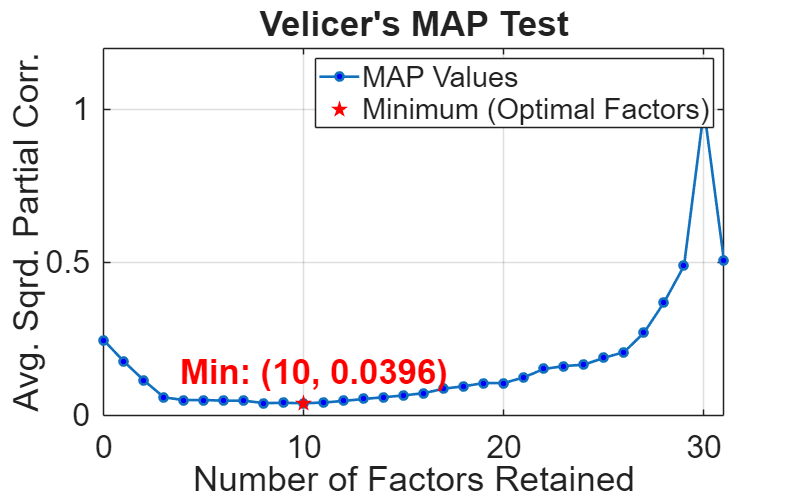

Velicer's MAP Test recommends retaining 10 factors.



[num_factors, map_values] = velicer_map(X_iVAE_input');

% 1. Create the Condition Vector (C) for the concatenated super-trial
% Starting simple: 2 classes! (Class 1 = BLT, Class 2 = P1)
numClasses = 2; 
nTime_concat = size(data_concat_all, 2);
C_trial = zeros(numClasses, nTime_concat);
nTime_cropped = length(time_cropped_BLT);
nTime_cropped_P12 = length(time_cropped_P12);

% --- Assign the 2 Classes ---
% The first half belongs to BLT
C_trial(1, 1:nTime_cropped) = 1; 

% The second half belongs to P1
C_trial(2, nTime_cropped+1:end) = 1;

% 2. Split data by whole trials (80% Train, 20% Test)
num_train_trials = floor(0.8 * min_trials);

rng(42); % For reproducibility
idx_rand = randperm(min_trials);
train_idx = idx_rand(1:num_train_trials);
test_idx = idx_rand(num_train_trials+1:end);

% Use the new concatenated array here
data_train = data_concat_all(:, :, train_idx);
data_test = data_concat_all(:, :, test_idx);

% 3. Reshape into 2D matrices for the network
X_train = reshape(data_train, num_ch, []);
X_test = reshape(data_test, num_ch, []);

% Rank of data
r = rank(X_train);

% 4. Replicate the Condition vector
C_train = repmat(C_trial, 1, length(train_idx));
C_test = repmat(C_trial, 1, length(test_idx));

% 5. Define iVAE Configuration
% NOTE: We are keeping the iVAE method and KL annealing!
cfg.method = "ivae"; 
cfg.bottleneckSize = num_sig_components; % num_sig_components, r-2
cfg.encoderLayerSizes = [64, 32];
cfg.decoderLayerSizes = [32, 64];
cfg.priorLayerSizes = [16];
cfg.epochs = 200;      
cfg.patience = 15; 
cfg.batchSize = 512;
cfg.learnRate = 5e-3;
cfg.beta = 0.1; 
cfg.warmupEpochs = 20;

sprintf('Training iVAE model with early stopping...\n');
% Notice we are passing X_test and C_test now
[encNet, decNet, priorNet, info] = trainEEGCVAE(X_train, C_train, X_test, C_test, cfg);

Epoch 1/200 - Train Loss: 13.2405 | Val Loss: 6.7358
Epoch 2/200 - Train Loss: 6.8565 | Val Loss: 6.2234
Epoch 3/200 - Train Loss: 6.5566 | Val Loss: 6.1528
Epoch 4/200 - Train Loss: 6.5106 | Val Loss: 6.1616
Epoch 5/200 - Train Loss: 6.5108 | Val Loss: 6.2079
Epoch 6/200 - Train Loss: 6.5226 | Val Loss: 6.2057
Epoch 7/200 - Train Loss: 6.5372 | Val Loss: 6.2321
Epoch 8/200 - Train Loss: 6.5578 | Val Loss: 6.2176
Epoch 9/200 - Train Loss: 6.5832 | Val Loss: 6.2350
Epoch 10/200 - Train Loss: 6.6056 | Val Loss: 6.2594
Epoch 11/200 - Train Loss: 6.6320 | Val Loss: 6.3072
Epoch 12/200 - Train Loss: 6.6603 | Val Loss: 6.3495
Epoch 13/200 - Train Loss: 6.6949 | Val Loss: 6.3626
Epoch 14/200 - Train Loss: 6.7208 | Val Loss: 6.3974
Epoch 15/200 - Train Loss: 6.7581 | Val Loss: 6.4148
Epoch 16/200 - Train Loss: 6.7887 | Val Loss: 6.4636
Epoch 17/200 - Train Loss: 6.8195 | Val Loss: 6.4658
Epoch 18/200 - Train Loss: 6.8584 | Val Loss: 6.5023
Early stopping triggered! Validation loss hasn't impro

## Plot Training and Validation Loss

fprintf('Plotting training and validation loss...\n');

Plotting training and validation loss...


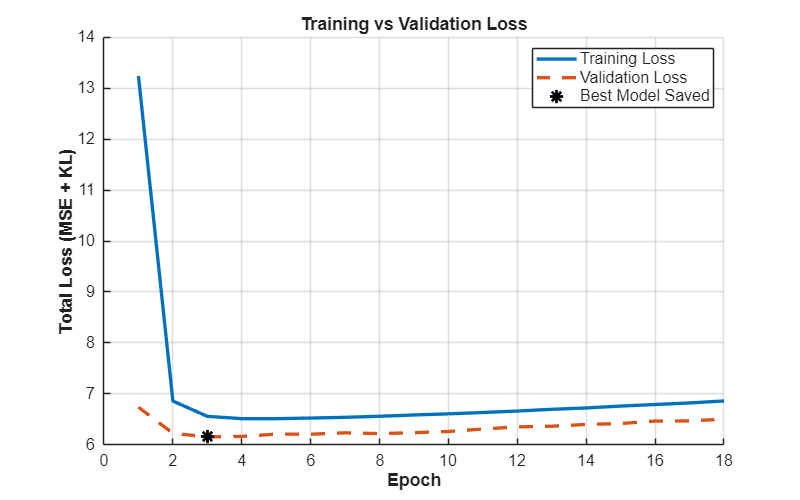

figure('Position', [150 150 800 500]);
hold on;
% Plot Train and Val loss
epochs_trained = length(info.lossHistory);
plot(1:epochs_trained, info.lossHistory, '-', 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Training Loss');
plot(1:epochs_trained, info.valLossHistory, '--', 'LineWidth', 2.5, 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'Validation Loss');

% Mark the best epoch (where the weights were actually saved)
[bestLoss, bestEpoch] = min(info.valLossHistory);
plot(bestEpoch, bestLoss, 'k*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Best Model Saved');
hold off;

grid on;
legend('Location', 'northeast', 'FontSize', 12);
xlabel('Epoch', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Total Loss (MSE + KL)', 'FontSize', 14, 'FontWeight', 'bold');
title('Training vs Validation Loss', 'FontSize', 16);
set(gca, 'FontSize', 12);

% Convert test data to dlarray format
X_test_dl = dlarray(X_test, 'CB');
C_test_dl = dlarray(C_test, 'CB');

% Concatenate Features (X) and Conditions (C) for the Encoder
XC_test = cat(1, X_test_dl, C_test_dl);

% Forward pass through the trained encoder to get the latent mean (zMu)
[zMu_test, zLogVar_test] = forward(encNet, XC_test);

% Extract the data from the deep learning array back into standard MATLAB matrices
latent_representations = extractdata(zMu_test);

fprintf('Latent representation extracted! Size: %d x %d\n', size(latent_representations, 1), size(latent_representations, 2));

Latent representation extracted! Size: 3 x 7632


## 4.0 Reshape iVAE Latents and Calculate Statistics

num_test_trials = length(test_idx);
num_comps = size(latent_representations, 1);
nTime_concat = size(data_test, 2);
nTime_BLT = length(time_cropped_BLT);
nTime_P12 = length(time_cropped_P12);
nTime_P13 = length(time_cropped_P13);
% Reshape back to (Latent Vars x Time x Trials)
% IMPORTANT: latent_representations comes from X_test, so we only divide by num_test_trials
Z_iVAE = reshape(latent_representations, num_comps, nTime_concat, num_test_trials);
fprintf('Latent representation reshaped! Size: %d x %d x %d\n', size(Z_iVAE, 1), size(Z_iVAE, 2), size(Z_iVAE, 3));

Latent representation reshaped! Size: 3 x 636 x 12



% Calculate Mean and Standard Deviation across the test trials (Dim 3)
Z_iVAE_mean = mean(Z_iVAE, 3);
Z_iVAE_std  = std(Z_iVAE, 0, 3);

## 5.0 Overlapping Mean Latent Traces (Baseline vs. Cued)

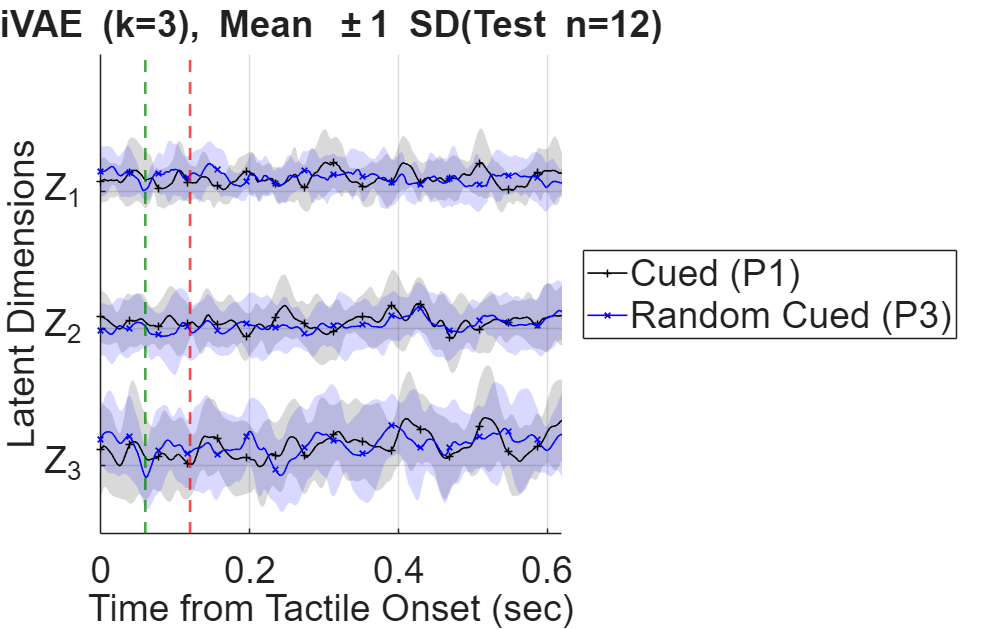

% Calculate dynamic offset based on peak-to-peak ranges
y_range = max(Z_iVAE_mean, [], 2) - min(Z_iVAE_mean, [], 2);
offset = max(y_range) * 2.3; 
if offset == 0 || isnan(offset), offset = 2; end 

% Setup Figure
fig_ivae = figure('Position', [50 50 1200 750]);
hold on;

% Create relative time vectors so both conditions start at t=0 for perfect overlap
rel_time_BLT = time_cropped_BLT - time_cropped_BLT(1);
rel_time_P13  = time_cropped_P13 - time_cropped_P13(1);
rel_time_P12  = time_cropped_P12 - time_cropped_P12(1);

% X-axis vectors for the 'fill' shading
time_fill_BLT = [rel_time_BLT, fliplr(rel_time_BLT)];
time_fill_P13  = [rel_time_P13, fliplr(rel_time_P13)];
time_fill_P12  = [rel_time_P12, fliplr(rel_time_P12)];

for pc = 1:num_comps
    % Calculate vertical shift for stacking (Component 1 at the top)
    y_shift = (num_comps - pc) * offset;
    
    % --- Split and Shift Means ---
    mean_P1 = Z_iVAE_mean(pc, 1:nTime_P13) + y_shift;
    mean_P3  = Z_iVAE_mean(pc, nTime_P13+1:end) + y_shift;
    
    % --- Split Standard Deviations ---
    std_P1 = Z_iVAE_std(pc, 1:nTime_P13);
    std_P3  = Z_iVAE_std(pc, nTime_P13+1:end);
    
    % --- Calculate Shading Bounds ---
    bound_P1 = [mean_P1 + std_P1, fliplr(mean_P1 - std_P1)];
    bound_P3  = [mean_P3 + std_P3, fliplr(mean_P3 - std_P3)];
    
    % 1. Plot Shaded Standard Deviation Areas (FaceAlpha 0.15)
    fill(time_fill_P13, bound_P1, 'k', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    fill(time_fill_P13, bound_P3, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    % 2. Plot Solid Mean Lines with Markers (spaced to prevent clutter)
    marker_spacing_P1 = 1:20:length(rel_time_P13);
    % marker_spacing_P1  = 1:20:length(rel_time_P1);
    
    plot(rel_time_P13, mean_P1, 'Color', 'k', 'Marker', '+', 'LineWidth', 1.2, ...
        'MarkerIndices', marker_spacing_P1, 'HandleVisibility', 'off');
        
    plot(rel_time_P13, mean_P3, 'Color', 'b', 'Marker', 'x', 'LineWidth', 1.2, ...
        'MarkerIndices', marker_spacing_P1, 'HandleVisibility', 'off');
end

% 0.06s in Dark Green
xline(0.06, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
% 0.12s in Red
xline(0.12, 'r--', 'LineWidth', 2);
% % 0.06s in Dark Green
% xline(1.56, '--',  'Color', [0 0.5 0], 'LineWidth', 2);
% % 0.12s in Red
% xline(1.62, 'r--',  'LineWidth', 2);

% --- Dummy handles for the Legend ---
h_P1 = plot(NaN, NaN, 'Color', 'k', 'Marker', '+', 'LineWidth', 1.2, 'DisplayName', 'Cued (P1)');
h_P3  = plot(NaN, NaN, 'Color', 'b', 'Marker', 'x', 'LineWidth', 1.2, 'DisplayName', 'Random Cued (P3)');

hold off;

% --- Formatting ---
ylim([-offset/2, num_comps * offset]);
xlim([0, max(max(rel_time_P13), max(rel_time_P13))]); 
xlabel('Time from Tactile Onset (sec)');
ylabel('Latent Dimensions');

% Dynamic title displaying bottleneck size and test trial count
title(['iVAE (k=' num2str(num_comps) '), Mean \pm1 SD(Test n=' num2str(num_test_trials) ')']);

% Set ascending ticks to show component numbers clearly
% Changed 'C' to 'Z' for standard VAE latent notation
yticks((0:num_comps-1) * offset);
yticklabels(arrayfun(@(c) sprintf('Z_{%d}', num_comps - c), ...
    0:num_comps-1, 'UniformOutput', false));

legend([h_P1, h_P3], 'Location', 'eastoutside'); % 'southoutside'
grid on;
set(findall(fig_ivae, '-property', 'FontSize'), 'FontSize', 28);